# HarmonicOscillatorExtended.mlx

Derives and plots symbolic solutions to driven damped harmonic oscillator for harmonic, step, impulse, and  ramp forcing functions.

Author: D. Carlsmith

clear

Declare symbols for manipulation.

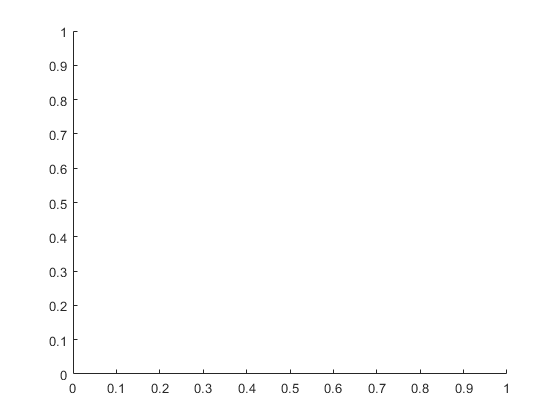

syms beta F omega0 x0 v0 real
syms x(t)

omega = [0 0.5 1 1.5 2];
omegazero = [1 1 1 1 1];
omegaprime  =  10*omega;
figure;hold on


for i=1:5
    ode = diff(x,t,2) + beta*diff(x,t,1) + omegazero(i)^2*x(t) == F*(cos(omega(i)*t) + cos(omegaprime(i) *t))
    
    cond1 = x(0)==x0;
    Dx = diff(x);
    cond2 = Dx(0)==v0;
    conds = [cond1 cond2];
    xSol(t) = dsolve(ode,conds);
    xSol = simplify(xSol);
end

$$ode(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+\beta \,\frac{\partial }{\partial t}x\left(t\right)+x\left(t\right)=2\,F$$

$$ode(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+\beta \,\frac{\partial }{\partial t}x\left(t\right)+x\left(t\right)=F\,\left(\cos\left(\frac{t}{2}\right)+\cos\left(5\,t\right)\right)$$

$$ode(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+\beta \,\frac{\partial }{\partial t}x\left(t\right)+x\left(t\right)=F\,\left(\cos\left(10\,t\right)+\cos\left(t\right)\right)$$

$$ode(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+\beta \,\frac{\partial }{\partial t}x\left(t\right)+x\left(t\right)=F\,\left(\cos\left(\frac{3\,t}{2}\right)+\cos\left(15\,t\right)\right)$$

$$ode(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+\beta \,\frac{\partial }{\partial t}x\left(t\right)+x\left(t\right)=F\,\left(\cos\left(2\,t\right)+\cos\left(20\,t\right)\right)$$

### Damped oscillator

Define ordinary differential equation for damped harmonic oscillator.

Define initial conditions (position and velocity).

Use [dsolve](https://www.mathworks.com/help/symbolic/dsolve.html) to find the solution in terms of initial conditions.

### Damped oscillator -harmonic driving force

Define differential equation for damped harmonic oscillator with harmonic force.

ode = diff(x,t,2)+beta*diff(x,t,1)+omega0^2*x(t)==F0*cos(omega *t)
cond1 = x(0)==x0;
Dx = diff(x);
cond2 = Dx(0)==v0;
conds = [cond1 cond2];

xSol(t) = dsolve(ode,conds);
xSol = simplify(xSol)

Generate a function of the parameters and time from the symbolic solution.

osc = matlabFunction(xSol)
test = func2str(osc);
display(test)

Plot the solution for displacement versus time for a range of frequencies about the natural frequeuncy (choosen to be 1) for a smallish Q value ( $\beta/\omega =0.1$). Note we printed osc to see the order of the arguments of the function.

figure;hold on
time=[0:.1:100];
leg=[];% start with empty legend

Loop over frequency values.

for omegaF=[0:.5:2]    

Call the function for all the time values.

    xosc=real(osc(time,.1,1,omegaF,1,0,0));
    plot(time,xosc)    

Add to the legend.

    leg=cat(1,leg,strcat("\omega_d = "+ num2str(omegaF)));
end
xlabel('t (s)');ylabel('x(t) (m)');
title('Oscillator displacement vs time, harmonic force,various drive frequencies')
legend(leg)

We can see the steady state amplitude is large when the drive frequency $\omega_d$ is close to the natural frequency.

### Damped oscillator - Heaviside step function

Solve damped harmonic oscillator for a [Heaviside step-function](https://en.wikipedia.org/wiki/Heaviside_step_function) force, stepping at t=0 from a value zero to a value F0, using [heaviside](https://www.mathworks.com/help/symbolic/heaviside.html). 

The differential equation for a force that vanishes for t<0 and is constant for t>0 is:

ode = diff(x,t,2)+beta*diff(x,t,1)+omega0^2*x(t)==F0*heaviside(t)
cond1 = x(0)==x0;
Dx = diff(x);
cond2 = Dx(0)==v0;
conds = [cond1 cond2];

The Heaviside step function is not smooth so ignore analytic constraints in using dsolve.

xSol(t) = dsolve(ode,conds,'IgnoreAnalyticConstraints', false);
xSol = simplify(xSol)

Generate a function of the parameters and time.

osc = matlabFunction(xSol)

Plot the solutions for various values of the natural frequency.

figure;hold on
time=[0:.1:100];
leg=[];% start with empty legend
F0val=1;betaval=.1;v0val=0;x0val=0;
for omega00=[.5:.5:2]
    xosc=real(osc(time,F0val,betaval,omega00,v0val,x0val));
    plot(time,xosc)
    leg=cat(1,leg,strcat("\omega_0 = "+ num2str(omega00)));%add to legend
end
xlabel('t (s)');ylabel('x(t) (m)');
title('Oscillator displacement vs time, step function force, various natural frequencies')
legend(leg)

### Damped oscillator - rampo force

FInd the solution for a damped harmonic oscillator subject to a smooth ramp force function governed by a ramp time $\tau$ represented by the hyperbolic tangent function $\tanh(x)=\sinh(x)/\cosh(x)=(e^x-e^{-x})/ (e^x-e^{-x})$ with $x=t/\tau$. For small $\tau$, this function is close to a step function. For large $\tau$, the function is a linear ramp.

Define differential equation for  the ramp force.

syms tau real
assume(tau>0)

MATLAB 2019b dsolve struggles to integrate the tanh so replace with exponential equivalent.

%ode = diff(x,t,2)+beta*diff(x,t,1)+omega0^2*x(t)==F0*tanh(t/tau)
ode = diff(x,t,2)+beta*diff(x,t,1)+omega0^2*x(t)==...
    F0*((exp(t/tau)-exp(-t/tau))/(exp(t/tau)-exp(-t/tau)))
cond1 = x(0)==x0;
Dx = diff(x);
cond2 = Dx(0)==v0;
conds = [cond1 cond2];
assume(beta<2*omega0)
assumeAlso(beta>0);assumeAlso(omega0>0)
xSol(t) = dsolve(ode,conds,'IgnoreAnalyticConstraints', false);
xSol = simplify(xSol)

Generate a function of the parameters and time.

 osc = matlabFunction(xSol)

Plot the solution for various values of natural frequency.

figure;hold on
leg=[];% start with empty legend
tauval=2.0;
for omega00=[.5:.5:2]
    for itime=[1:1000]
    time(itime)=itime*.1;
    xosc(itime)=real(osc(time(itime),1.,.1,omega00,0.,0.));
    end
    plot(time,xosc)
    leg=cat(1,leg,strcat("\omega_0 = "+ num2str(omega00)));%add to legend
end
xlabel('t (s)');ylabel('x(t) (m)');
title('Oscillator displacement vs time, ramp function force, various natural frequencies')
legend(leg)

### Damped oscillator - impulse force

Find the solution for a damped harmonic oscillator subject to an impulsive force. This solution is essentially the Green's function. The impulsive force is represented by a [Dirac delta function](https://en.wikipedia.org/wiki/Dirac_delta_function) using [dirac](https://www.mathworks.com/help/symbolic/dirac.html).

Define differential equation for  force that vanishes for t<0 and for t>0 and is infinite for t=0.

ode = diff(x,t,2)+beta*diff(x,t,1)+omega0^2*x(t)==F0*dirac(t)
cond1 = x(0)==x0;
Dx = diff(x);
cond2 = Dx(0)==v0;
conds = [cond1 cond2];

The dirac impulse function is not smooth so ignore analytic constraints.

xSol(t) = dsolve(ode,conds,'IgnoreAnalyticConstraints', false);
xSol = simplify(xSol)

Generate a function of the parameters and time.

osc = matlabFunction(xSol)

Plot the solution for various values of natural frequency.

figure;hold on
time=[0:.1:100];
leg=[];% start with empty legend
for omega00=[.5:.5:2]
    xosc=real(osc(time,1,.1,omega00,0,0));
    plot(time,xosc)
    leg=cat(1,leg,strcat("\omega_0 = "+ num2str(omega00)));%add to legend
end
xlabel('t (s)');ylabel('x(t) (m)');
title('Oscillator displacement vs time, impulse function force, various natural frequencies')
legend(leg)